%%
% 5281873
clc
close all
clear all

% setup
a = 5; b = 8; c = 3;

NCS.A = [a-b 0.5-c;
         0   1];

NCS.B = [0; 1];

NCS.nx = 2;

% Q1.1
% i = 1.8;
% q = 0.8;
a1 = 1.0;
b1 = 1.0;
NCS.poles = [-a1+b1*i -a1-b1*i];

NCS.K = place(NCS.A, NCS.B, NCS.poles)

NCS = struct with fields:
        A: [2×2 double]
        B: [2×1 double]
       nx: 2
    poles: [-1.0000 + 1.0000i -1.0000 - 1.0000i]
        K: [-2.0000 0]


eig(NCS.A - NCS.B * NCS.K)

ans =   -1.0000 + 1.0000i
  -1.0000 - 1.0000i



clear ans a1 b1

% Q1.2
syms h tau s
NCS.h = h; NCS.tau = tau;

NCS_no_delay.F = expm(NCS.A * NCS.h);

NCS_no_delay.G = (NCS_no_delay.F - eye(NCS.nx)) / NCS.A * NCS.B;

NCS_no_delay.A = NCS_no_delay.F - NCS_no_delay.G * NCS.K;

fprintf("system(no delay) matrix A is");

system(no delay) matrix A is

NCS_no_delay.A

 
ans =
 
        [0.583333333333333 exp(-3. h) - 1.25000000000000 exp(h)

         + 1.66666666666667 ,

        0.625000000000000 exp(-3. h) - 0.625000000000000 exp(h)]

        [-2.00000000000000 + 2.00000000000000 exp(h) , exp(h)]



% give an example
% NCS_no_delay.A_double = double(vpa(subs(NCS_no_delay.A, [h, tau], [0.9, 0])));

NCS_no_delay.A_eig = eig(NCS_no_delay.A)

NCS_no_delay = struct with fields:
        F: [2×2 sym]
        G: [2×1 sym]
        A: [2×2 sym]
    A_eig: [2×1 sym]



fprintf("max eigenvalue with ([h, tau], [0.9, 0])");

max eigenvalue with ([h, tau], [0.9, 0])

% max(abs(eig(NCS_no_delay.A_double)))
temp = vpa(subs(NCS_no_delay.A_eig, [h, tau], [0.9, 0]));

max(double(abs(temp)))

ans = 0.9993


clear temp

% Q2.1
% NCS_small_delay.G1 = (expm(NCS.A * (NCS.h - NCS.tau)) - eye(NCS.nx)) / NCS.A * NCS.B;
% 
% temp = (NCS_no_delay.F - eye(NCS.nx)) / NCS.A * NCS.B;
% 
% NCS_small_delay.Fu = temp - NCS_small_delay.G1;

NCS_small_delay.Fx = expm(NCS.A * NCS.h);

temp = expm(NCS.A * s);

NCS_small_delay.Fu = int(temp, s, h-tau, h) * NCS.B;
NCS_small_delay.G1 = int(temp, s, 0, h-tau) * NCS.B;

% augmentation
NCS_small_delay.F = [NCS_small_delay.Fx NCS_small_delay.Fu;
                     zeros(1, size([NCS_small_delay.Fx, NCS_small_delay.Fu], 2))];

NCS_small_delay.G = [NCS_small_delay.G1;
                     eye(size(NCS_small_delay.G1, 2))]

NCS_small_delay = struct with fields:
    Fx: [2×2 sym]
    Fu: [2×1 sym]
    G1: [2×1 sym]
     F: [3×3 sym]
     G: [3×1 sym]



NCS_small_delay.A = NCS_small_delay.F - NCS_small_delay.G * [NCS.K 0];

fprintf("system(small delay) matrix A is");

system(small delay) matrix A is

NCS_small_delay.A

 
ans =
 
        [1. exp(-3. h) + 1.66666666660000 - 1.25000000000000 exp(h - 1. tau)

         - 0.416666666600000 exp(-3. h + 3. tau) ,

        0.625000000000000 exp(-3. h) - 0.625000000000000 exp(h) ,

        0.6250000000 exp(h - 1. tau) + 0.2083333333 exp(-3. h + 3. tau)

         - 0.6250000000 exp(h) - 0.2083333333 exp(-3. h)]

        [-2.00000000000000 + 2.00000000000000 exp(h - tau) , exp(h) ,

        -exp(h - tau) + exp(h)]

        [2.00000000000000 , 0. , 0.]



NCS_small_delay.A_eig = eig(NCS_small_delay.A)

NCS_small_delay = struct with fields:
       Fx: [2×2 sym]
       Fu: [2×1 sym]
       G1: [2×1 sym]
        F: [3×3 sym]
        G: [3×1 sym]
        A: [3×3 sym]
    A_eig: [3×1 sym]



% give an example

fprintf("max eigenvalue with ([h, tau], [0.5, 0.1*0.1])");

max eigenvalue with ([h, tau], [0.5, 0.1*0.1])

% NCS_small_delay.A_double = double(vpa(subs(NCS_small_delay.A, [h, tau], [0.9, 0.1*0.1])));
% 
% max(abs(eig(NCS_small_delay.A_double)))

temp = vpa(subs(NCS_small_delay.A_eig, [h, tau], [0.8, 0]));

max(double(abs(temp)))

ans = 0.9519


clear temp

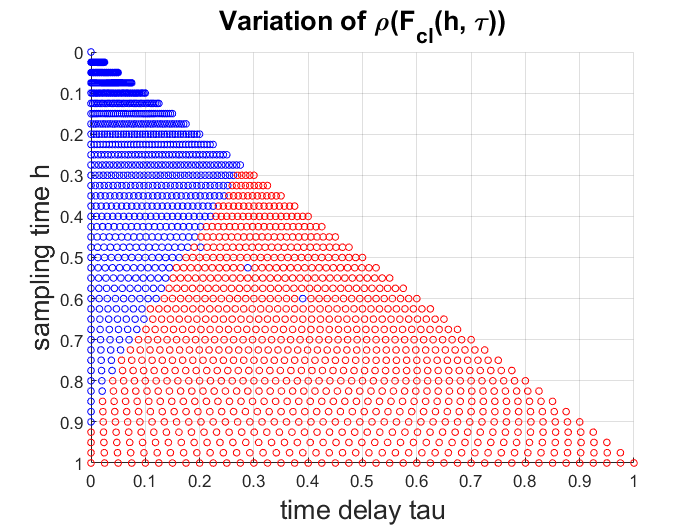

% Q2.2
h_samples = [0 : 0.025 : 1.0];
% around 2.2 is unstable
tau_samples = [0 : h_samples(end)/10 : 0.8*h_samples(end)];
results = zeros([1, (length(h_samples)*length(tau_samples))]);
plot_h = zeros([1, (length(h_samples)*length(tau_samples))]);
plot_tau = zeros([1, (length(h_samples)*length(tau_samples))]);

for i = 1 : length(h_samples)
    tau_samples = [0 : h_samples(i)/40 : h_samples(i)];
    for j = 1 : length(tau_samples)
%         NCS_small_delay.A_double = double(vpa(subs(NCS_small_delay.A, [h, tau], [h_samples(i), tau_samples(j)])));
        
        temp = vpa(subs(NCS_small_delay.A_eig, [h, tau], [h_samples(i), tau_samples(j)]));

        rho = max(double(abs(temp)));
        
        k = ((i-1)*length(tau_samples)+j);
        results(1, k) = rho;
        plot_h(1, k) = h_samples(i);
        plot_tau(1, k) = tau_samples(j);
    end
end


figure
inx = find(results >= 1);
plot3(plot_h(inx), plot_tau(inx), results(inx), 'o', 'color', 'r', 'MarkerSize', 4)
grid on
hold on
inx = find(results < 1);
plot3(plot_h(inx), plot_tau(inx), results(inx), 'o', 'color', 'b', 'MarkerSize', 4)

% plot3(plot_h(1:33:end), plot_tau(1:1:27), results(1:33:end), 'r')
xlabel("sampling time h", 'FontSize', 16); 
ylabel("time delay tau", 'FontSize', 16);
zlabel("\rho(F_{cl}(h, \tau))", 'FontSize', 16);
title("Variation of \rho(F_{cl}(h, \tau))", 'FontSize', 16)
view(90,90)


clear temp rho i j k inx ans

clear h_samples tau_samples

clear plot_h plot_tau results


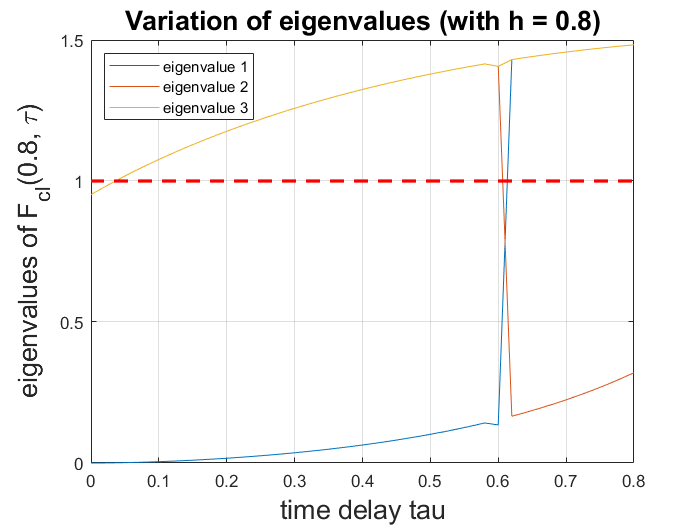

% Q2.3
% we choose h = 1.4
h_sample = 0.8; 
tau_sample = [0 : h_sample/40 : h_sample];
rho = zeros(3, length(tau_sample));
rho1 = zeros(3, length(tau_sample));

for i = 1:length(tau_sample)
    temp = (vpa(subs(NCS_small_delay.A_eig, [h, tau], [h_sample, tau_sample(i)])));
    rho(:, i) = double(abs(temp));
end

figure;
plot(tau_sample, rho')
grid on
hold on
plot(tau_sample, ones(1, length(tau_sample)), 'r--', 'LineWidth', 2)
xlabel("time delay tau", 'FontSize', 16); 
ylabel("eigenvalues of F_{cl}(0.8, \tau)", 'FontSize', 16);
title("Variation of eigenvalues (with h = 0.8)", 'FontSize', 16)
legend({'eigenvalue 1', 'eigenvalue 2', 'eigenvalue 3'}, 'Location', 'northwest')


clear i 

% we retune the K
a1 = 1.0;
b1 = 1.3;
% NCS.poles = [-a+b*a -a-b*a];
NCS.poles = [-a1+b1*i -a1-b1*i];
NCS.K = place(NCS.A, NCS.B, NCS.poles);

NCS = struct with fields:
        A: [2×2 double]
        B: [2×1 double]
       nx: 2
    poles: [-1.0000 + 1.3000i -1.0000 - 1.3000i]
        K: [-2.2760 2.2204e-16]
        h: [1×1 sym]
      tau: [1×1 sym]


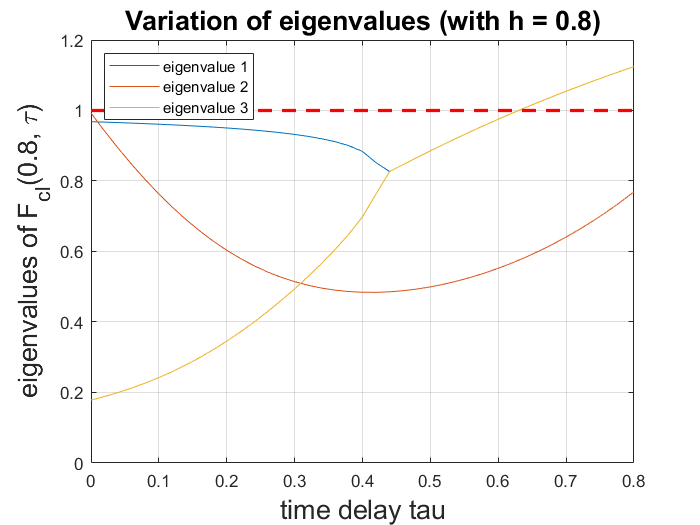


K = [NCS.K 0.85];

NCS_small_delay.A_retune = NCS_small_delay.F - NCS_small_delay.G * K;
NCS_small_delay.A_eig_retune = eig(NCS_small_delay.A_retune);

for i = 1:length(tau_sample)
    temp = (vpa(subs(NCS_small_delay.A_eig_retune, [h, tau], [h_sample, tau_sample(i)])));
    rho1(:, i) = double(abs(temp));
end

figure;
plot(tau_sample, rho1')
grid on
hold on
plot(tau_sample, ones(1, length(tau_sample)), 'r--', 'LineWidth', 2)
xlabel("time delay tau", 'FontSize', 16); 
ylabel("eigenvalues of F_{cl}(0.8, \tau)", 'FontSize', 16);
title("Variation of eigenvalues (with h = 0.8)", 'FontSize', 16)
legend({'eigenvalue 1', 'eigenvalue 2', 'eigenvalue 3'}, 'Location', 'northwest')



clear i tau_sample h_sample a b


% Q3.1
NCS_large_delay.Fx = expm(NCS.A * NCS.h);

temp = expm(NCS.A*s);

NCS_large_delay.Fu2 = int(temp, s, NCS.tau-2*NCS.h, NCS.h) * NCS.B;
NCS_large_delay.Fu3 = int(temp, s, 0, NCS.tau-2*NCS.h) * NCS.B;

NCS_large_delay.F=[NCS_large_delay.Fx, zeros(2,1), NCS_large_delay.Fu2, NCS_large_delay.Fu3;
                   0, 0, 0, 0, 0;
                   0, 0, 1, 0, 0;
                   0, 0, 0, 1, 0];
NCS_large_delay.G = [0; 0; 1; 0; 0];

NCS_large_delay.A = NCS_large_delay.F - NCS_large_delay.G * [NCS.K 0 0 0];

fprintf("system(small delay) matrix A is");

system(small delay) matrix A is

NCS_large_delay.A

 
ans =
 
        [1. exp(-3. h) ,

        0.625000000000000 exp(-3. h) - 0.625000000000000 exp(h) , 0. ,

        0.6250000000 exp(tau - 2. h) + 0.2083333333 exp(-3. tau + 6. h)

         - 0.6250000000 exp(h) - 0.2083333333 exp(-3. h) , 0.833333333300000

         - 0.6250000000 exp(tau - 2. h) - 0.2083333333 exp(-3. tau + 6. h)]

        [0. , exp(h) , 0. , -exp(tau - 2 h) + exp(h) , -1. + exp(tau - 2 h)]

        [2.00000000000000 , 0. , 0. , 0. , 0.]

        [0. , 0. , 1. , 0. , 0.]

        [0. , 0. , 0. , 1. , 0.]



NCS_large_delay.A_eig = eig(NCS_large_delay.A)

NCS_large_delay = struct with fields:
              Fx: [2×2 sym]
             Fu2: [2×1 sym]
             Fu3: [2×1 sym]
               F: [5×5 sym]
               G: [5×1 double]
               A: [5×5 sym]
           A_eig: [1×1 sym]
        A_retune: [5×5 sym]
    A_eig_retune: [1×1 sym]



% give an example

fprintf("max eigenvalue with ([h, tau], [0.5, 0.1*0.1])");

max eigenvalue with ([h, tau], [0.5, 0.1*0.1])


temp = vpa(subs(NCS_large_delay.A_eig, [h, tau], [1.0, 2*1.0]));

max(double(abs(temp)))

ans = 2.3458e-11


clear temp

% Q3.2

% i = 1.9;
% q = 0.8;
a1 = 1.0;
b1 = 1.0;
NCS.poles = [-a1+b1*i -a1-b1*i];
NCS.K = place(NCS.A, NCS.B, NCS.poles);

NCS = struct with fields:
        A: [2×2 double]
        B: [2×1 double]
       nx: 2
    poles: [-1.0000 + 1.0000i -1.0000 - 1.0000i]
        K: [-2.0000 0]
        h: [1×1 sym]
      tau: [1×1 sym]


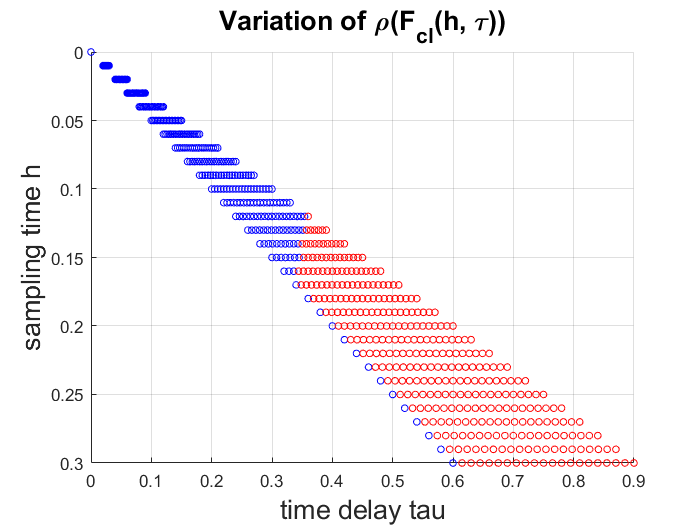


h_samples = [0 : 0.01 : 0.3];
% around 2.2 is unstable
tau_samples = [0 : h_samples(end)/10 : 0.8*h_samples(end)];
results = zeros([1, (length(h_samples)*length(tau_samples))]);
plot_h = zeros([1, (length(h_samples)*length(tau_samples))]);
plot_tau = zeros([1, (length(h_samples)*length(tau_samples))]);

for i = 1 : length(h_samples)
    tau_samples = [2*h_samples(i) : h_samples(i)/20 : 3*h_samples(i)];
    for j = 1 : length(tau_samples)
%         NCS_small_delay.A_double = double(vpa(subs(NCS_small_delay.A, [h, tau], [h_samples(i), tau_samples(j)])));
        
        temp = vpa(subs(NCS_large_delay.A_eig, [h, tau], [h_samples(i), tau_samples(j)]));

        rho = max(double(abs(temp)));
        
        k = ((i-1)*length(tau_samples)+j);
        results(1, k) = rho;
        plot_h(1, k) = h_samples(i);
        plot_tau(1, k) = tau_samples(j);
    end
end


figure
inx = find(results >= 1);
plot3(plot_h(inx), plot_tau(inx), results(inx), 'o', 'color', 'r', 'MarkerSize', 4)
grid on
hold on
inx = find(results < 1);
plot3(plot_h(inx), plot_tau(inx), results(inx), 'o', 'color', 'b', 'MarkerSize', 4)

% plot3(plot_h(1:33:end), plot_tau(1:1:27), results(1:33:end), 'r')
xlabel("sampling time h", 'FontSize', 16); 
ylabel("time delay tau", 'FontSize', 16);
zlabel("\rho(F_{cl}(h, \tau))", 'FontSize', 16);
title("Variation of \rho(F_{cl}(h, \tau))", 'FontSize', 16)
view(90,90)


clear temp rho i j k inx ans

clear h_samples tau_samples

clear plot_h plot_tau results

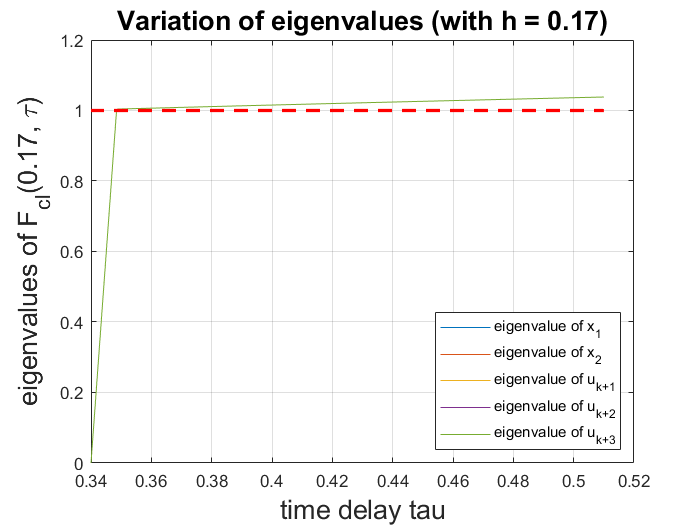

% Q3.3
% we choose h = 0.2
h_sample = 0.17; 
tau_sample = [2*h_sample : h_sample/20 : 3*h_sample];
rho = zeros(5, length(tau_sample));
rho1 = zeros(5, length(tau_sample));

for i = 1:length(tau_sample)
    temp = (vpa(subs(NCS_large_delay.A_eig, [h, tau], [h_sample, tau_sample(i)])));
    rho(:, i) = double(abs(temp));
end

figure;
plot(tau_sample, rho')
grid on
hold on
plot(tau_sample, ones(1, length(tau_sample)), 'r--', 'LineWidth', 2)
% xlim([0.4, 0.7]);
xlabel("time delay tau", 'FontSize', 16); 
ylabel("eigenvalues of F_{cl}(0.17, \tau)", 'FontSize', 16);
title("Variation of eigenvalues (with h = 0.17)", 'FontSize', 16)
legend({'eigenvalue of x_1', 'eigenvalue of x_2', 'eigenvalue of u_{k+1}', 'eigenvalue of u_{k+2}', 'eigenvalue of u_{k+3}'}, 'Location', 'southeast')


clear i 

% we retune the K
a1 = 1.0;
b1 = 1.0;
NCS.poles = [-a1+b1*i -a1-b1*i];

NCS.K = place(NCS.A, NCS.B, NCS.poles);

NCS = struct with fields:
        A: [2×2 double]
        B: [2×1 double]
       nx: 2
    poles: [-1.0000 + 1.0000i -1.0000 - 1.0000i]
        K: [-2.0000 0]
        h: [1×1 sym]
      tau: [1×1 sym]


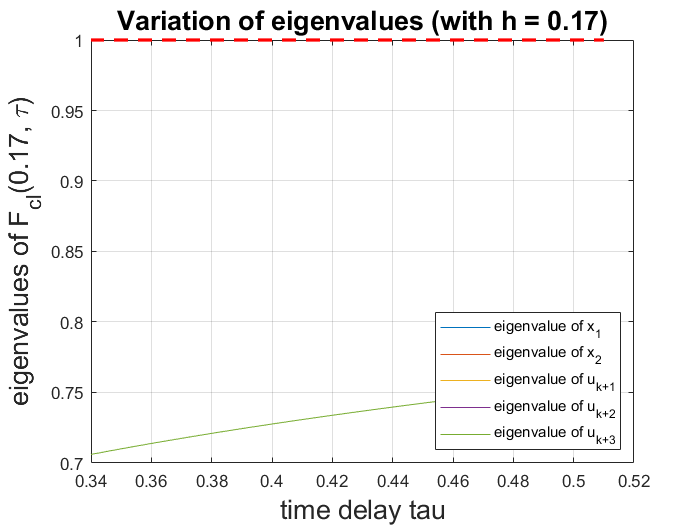


K = [NCS.K 0.5 0.5 0.5];

NCS_large_delay.A_retune = NCS_large_delay.F - NCS_large_delay.G * K;
NCS_large_delay.A_eig_retune = eig(NCS_large_delay.A_retune);

for i = 1:length(tau_sample)
    temp = (vpa(subs(NCS_large_delay.A_eig_retune, [h, tau], [h_sample, tau_sample(i)])));
    rho1(:, i) = double(abs(temp));
end

figure;
plot(tau_sample, rho1')
grid on
hold on
plot(tau_sample, ones(1, length(tau_sample)), 'r--', 'LineWidth', 2)
xlabel("time delay tau", 'FontSize', 16); 
ylabel("eigenvalues of F_{cl}(0.17, \tau)", 'FontSize', 16);
title("Variation of eigenvalues (with h = 0.17)", 'FontSize', 16)
legend({'eigenvalue of x_1', 'eigenvalue of x_2', 'eigenvalue of u_{k+1}', 'eigenvalue of u_{k+2}', 'eigenvalue of u_{k+3}'}, 'Location', 'southeast')



clear a1 b1

% clear tau_sample h_sample
